
clear all;
close all;


**DEFINIZIONE DELL'INNER LOOP**

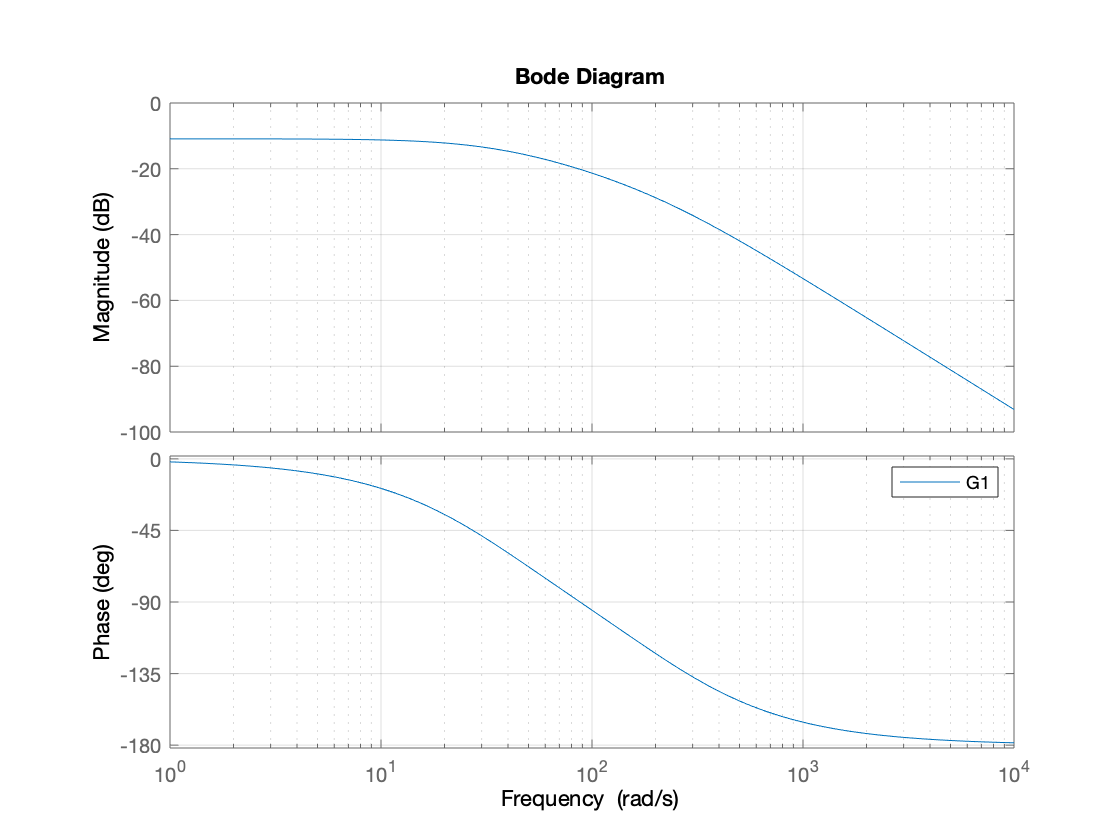

p=35; %in realtà il valore può variare tra 20 e 35
G1 = zpk([],[-p,-220],2200);
bode (G1); grid on; legend ();

[num_G1,den_G1] = tfdata(G1,'v');


**CONTROLLO IN CASCATA**

Per attenuare il disturbo d1 che esiste nell'intervallo [0;1] r/s uso un guadagno statico, calcolato grazie al *teorema del regime permante *da cui si deduce che ad 1 r/s la L(s) deve avere un modulo maggiore di 38.06 dB (quindi considerando che la G1(s) inizialmente è -11 dB il mu deve portare un'amplificazione di 49.06 dB). Dato il polo incerto in G2, quello con specifiche peggiori in questo caso è p = 35.

Per avere l'inseguimento di W e quindi errore nullo mi basta il polo nell'origine già presente in G2, come verificabile tramite il *teorema del valore finale.*

`INNER LOOP`

PROGETTO DEL REGOLATORE STATICO

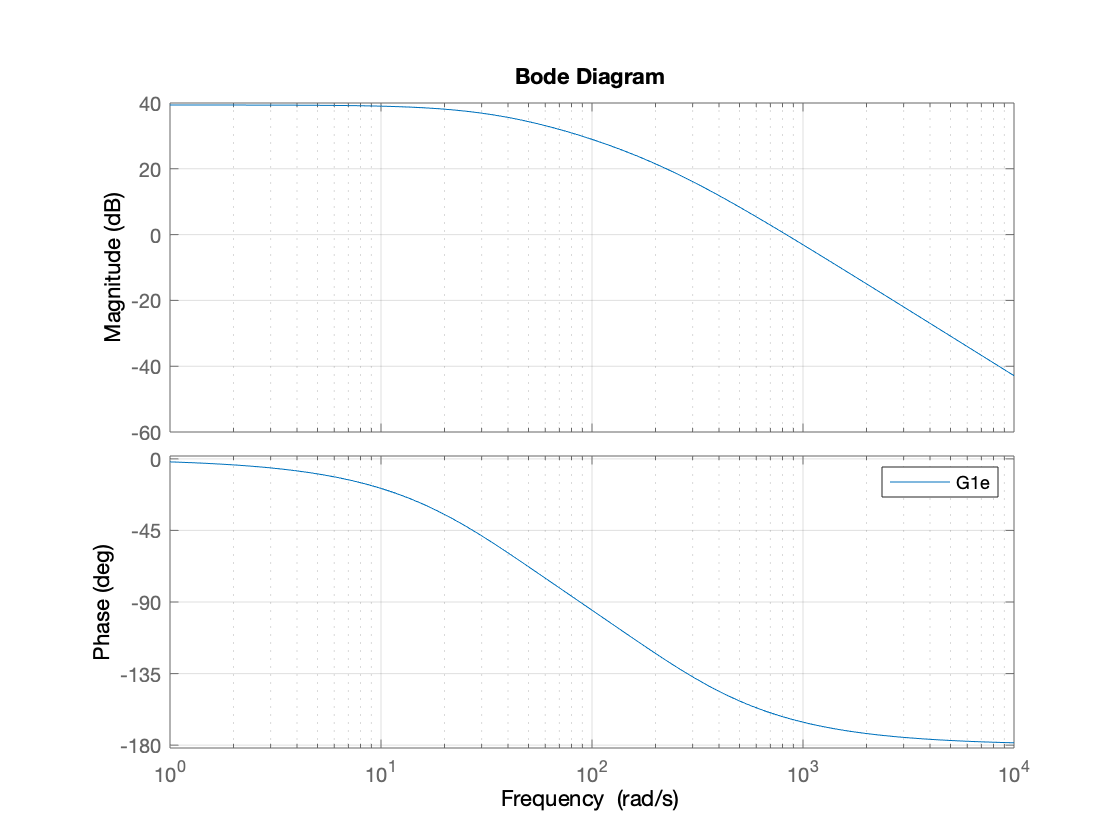

mu1 = 283.79;
mu2 = 1.15; %mu2 aggiunto per via dell'attenuazione dovuta alla rete 
%ritardatrice che avviene anche nell'intervallo in cui esiste il disturbo
%d1
mu = mu1*mu2;
G1e = G1*mu;
bode (G1e); grid on; legend ();

PROGETTO DEL REGOLATORE DINAMICO

Per attenuare il disturbo di misura n1, che agisce ad una frequenza di 8000 r/s con ampiezza 0.2,  ricaviamo l'upper-bound ω_ci ≤ 800 r/s (una decade prima di n1). Osservando l'outer loop e la specifica sul tempo di assestamento noto un lower bound per la omega_co a 10 r/s, poiché l'inner loop è buona regola che attraversi una decade dopo l'outer, ho deciso di prendere omega_ci  = 150 r/s e quindi omega_co = 15 r/s. Dal bode della G1e si nota che il sistema è in uno scenario A e decido quindi di applicare una rete ritardatrice.

Per progettare la rete anticipatrice mi sono affidato al *tuninig pratico* da cui segue:                                       20log(alpha) = -|Ge(jWc)|. Dopodichè il tuning pratico suggerirebbe di posizionare lo zero una decade prima il polo (alpha*tau = 10/ω_c), ma dato che a 150 r/s abbiamo più fase di quella che mi servirebbe, decido di tartare tau affinchè la coppia polo-zero si sposti ed attenui il meno possibile ad 1 r/s (dove agisce il disturbo sull'uscita) purché il margine di fase rimanga comunque di almeno 40º. Nonostante la coppia polo-zero venga spostata, rimane una piccola attenuazione ad 1 r/s che risolvo con l'introduzione di mu2=1.15. (La formula dunque utlizzata per trovare tau è: alpha*tau = 5/ω_c)

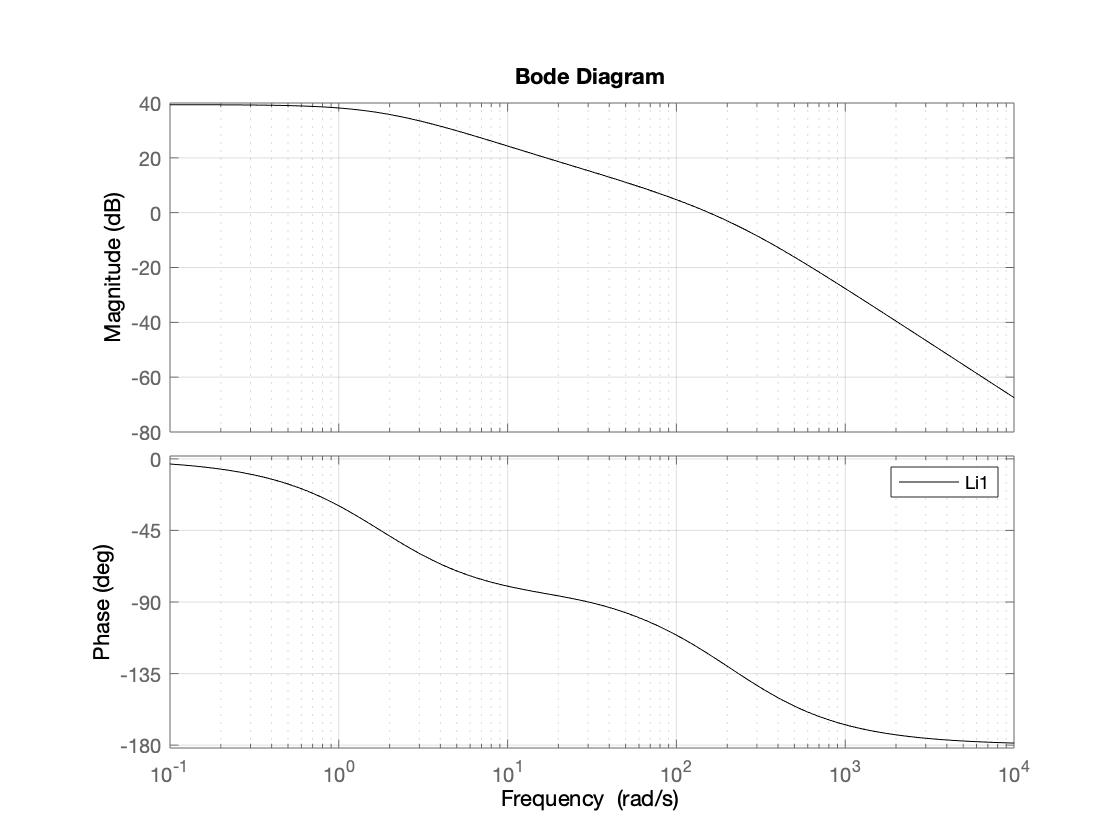

s=tf('s');
alpha = 0.059;
tau = 0.566;
Rdi1 = (alpha*tau*s + 1)/(tau*s + 1); %rete ritardatrice

Li1 = Rdi1*G1e;
bode(Li1, 'black'); grid on; legend ();
hold on;
hold off;

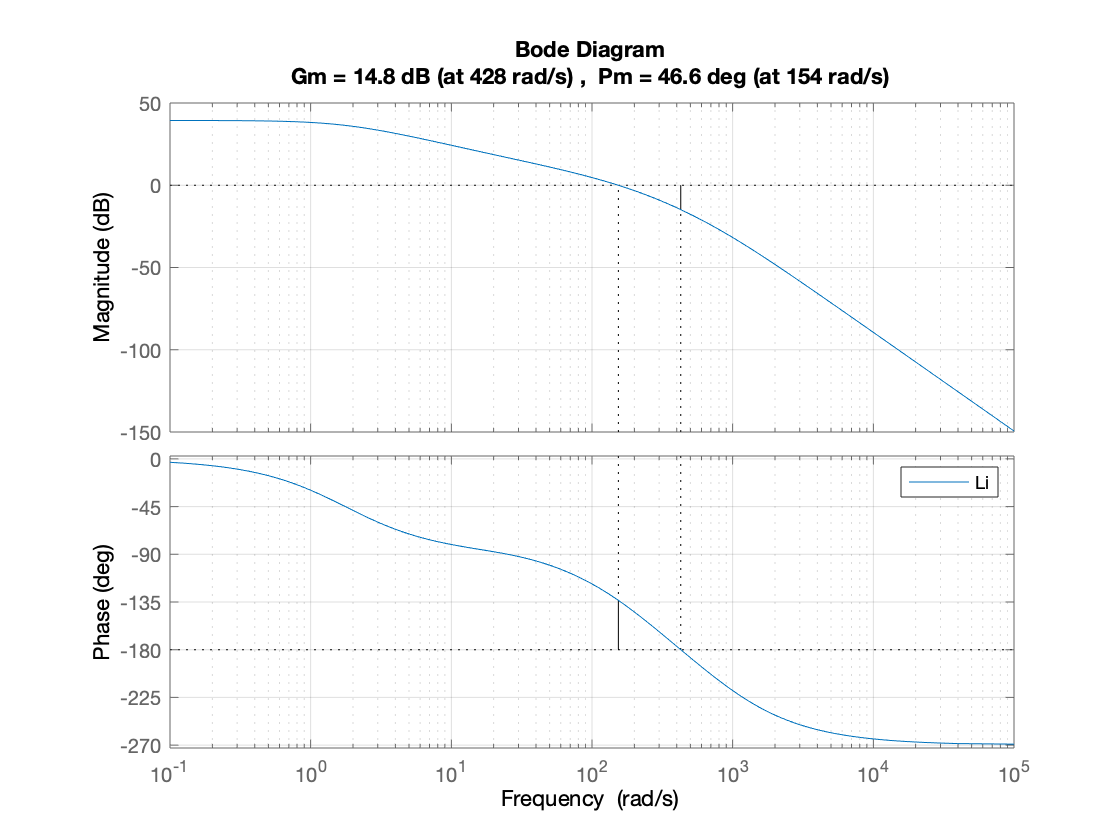

%Serve un polo di fiisca realizzabilità per moderare la Q ad elevate
%frequenze
Rdi2 = 1/((1/800)*s+1);
Rdi = Rdi1*Rdi2;
[num_Rdi,den_Rdi] = tfdata(Rdi,'v');

Li = Rdi*G1e;
margin(Li); grid on; legend ();
hold on;
hold off;

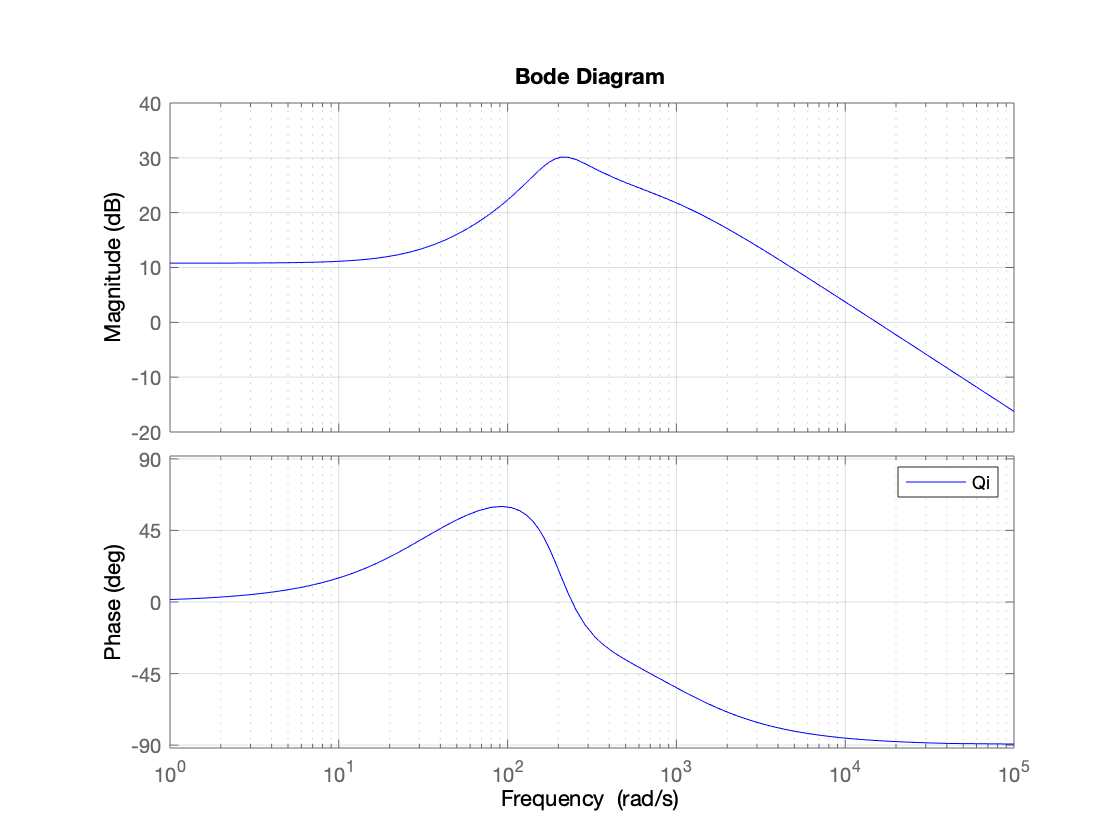

Qi = (Rdi*mu)/(Li+1); %definisco la Q dell'inner loop
bode (Qi, 'blue'); grid on; legend ();

Ri = Rdi*mu; %rinomino il regolatore dell'inner completo cosi per poterlo 
%in modo compatto più avanti


**DEFINIZIONE DEL SISTEMA OUTER LOOP**

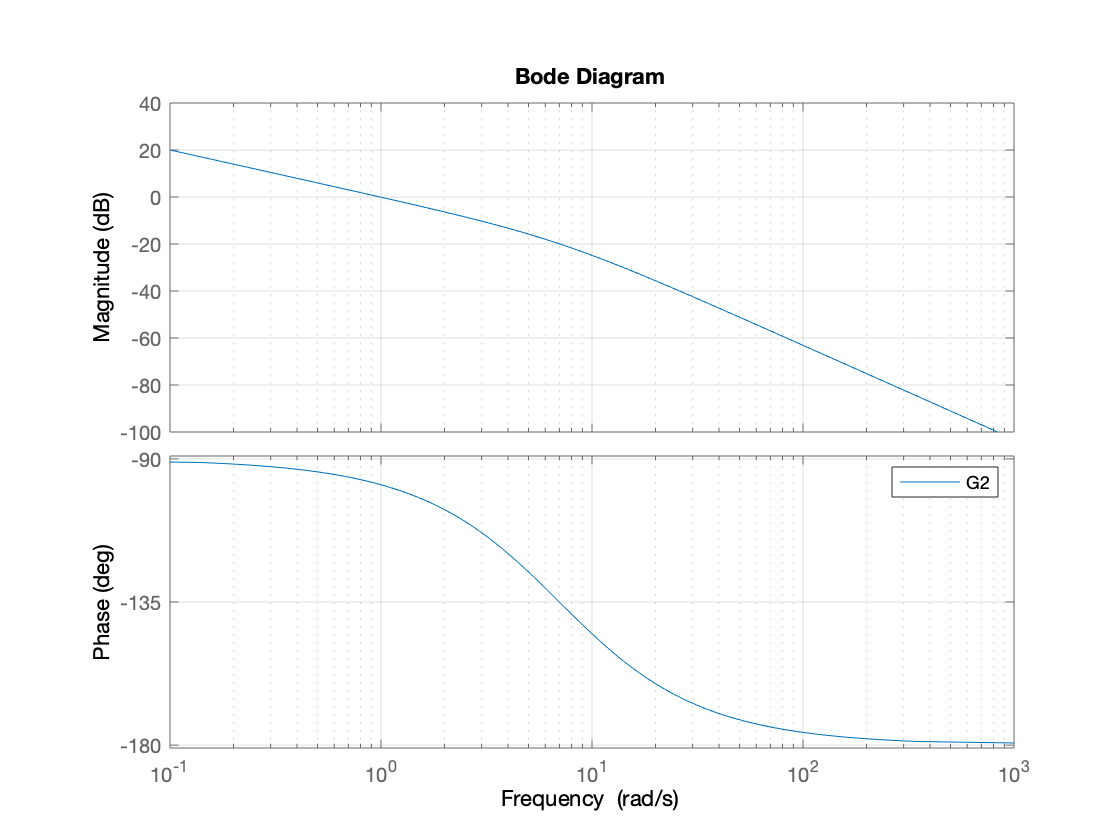

G2 = zpk([],[0,-7],7);
bode (G2); grid on; legend ();

[num_G2,den_G2] = tfdata(G2,'v');

**PROGETTO DEL REGOLATORE DINAMICO**

Le specifiche sulla sovraelogazione, che deve essere nulla, impongono un  𝛿 ≥ 0.75. Attraverso le formule approssimate posso anche dedurre un Mf = 75º che è però maggiore di quello richiesto dalle specifiche del progetto. Decido dunque di seguire la specifica Mf=40º (considerando comunque 𝛿 = 0.75), perchè richiedere troppo margine di fase implica l'utilizzo di più zeri per guadagnare fase, rischiando di avere grossi problemi di code di assestamento. Ovviamente un margine di fase minore mi comporta una sovraelongazione fuori specifica che verrà attenuta con un pre-filtro passa basso.

Data la specifica sul tempo di assestamento (Ta_5% = 0.4 sec) è possibile ricavare il lower-bound (ω_c ≥ 10 r/s) per la pulsazione di attraversamento della L(s), sapendo che ω_n = ω_c e che 𝛿 = 0.75.

Invece per attenuare il disturbo di misura n2, che agisce ad una frequenza di 8000 r/s con ampiezza 0.02,  ricaviamo l'upper-bound ω_c ≤ 800 r/s (una decade prima di n2).

Poiché la pulsazione di attraversamento scelta è ω_c = 15r/s il sistema si trova in uno scenario di tipo B e necessita dunque di una rete anticipatrice.


%proviamo a non usare il mu, ma solo una rete anticipatrice
%[alpha2, tau2] = ProgettaRA (G2, 15, 50)
%noto che il sistema cosi progettato ha delle code di assestamento decido
%quindi di usare anche il guadagno per provare a risolvere questo problema.
%Per un'altra soluzione possibile confronta "cancellazione.m"


Provo dunque a progettare una rete anticipatrice per avere il picco di sfasamento a 15r/s e usare il mu libero per imporre l'attraversamento alla pulsazione desiderata. Per fare ciò uso le formule del tuning pratico: fase_guadagata = asin((1-alpha)/(1+alpha)) e wb=1/(tau*sqrt(alpha)).

Potrei anche richiedere 75° di fase e ottenere così un margine di fase di 100°, andando ad annullare completamente la sovraelongazione, però dalle simulazioni effettuate risulta che non vengono risolti i problemi di code di assestamento e la moderazione del controllo non è ottimale. Richiedo allora di avere un margine di fase di 50°, mi tengo un piccolo margine di errore, che sicuramente farà sì che la specifica sulla sovraelongazione non verrà rispettata (uso un pre-filtro passa basso). Usando le formule sopra riportate identifico alpha e tau come sotto:

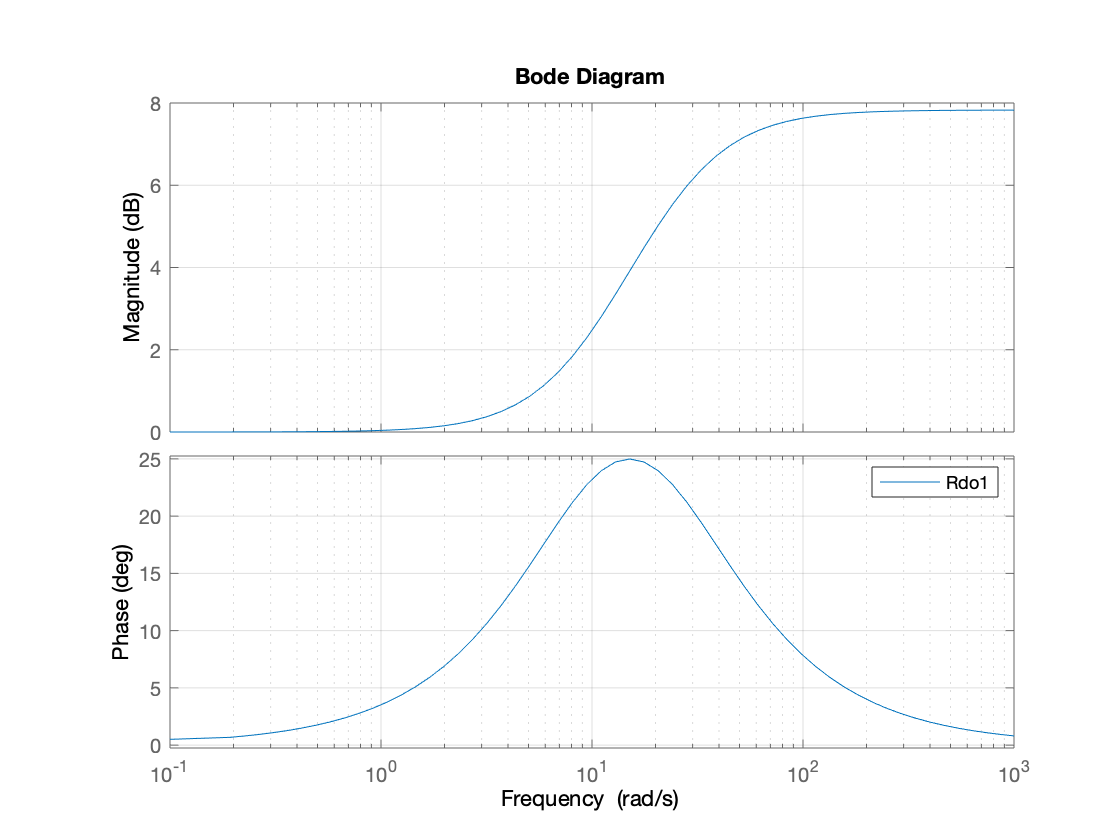

alpha2 = 0.406; %fase guadagnata = 25º
tau2 = 0.104; %lo zero in 9.61 (meglio anche per le code di assestamento)
Rdo1 = (tau2*s + 1)/(alpha2*tau2*s + 1);
bode (Rdo1); grid on; legend ();

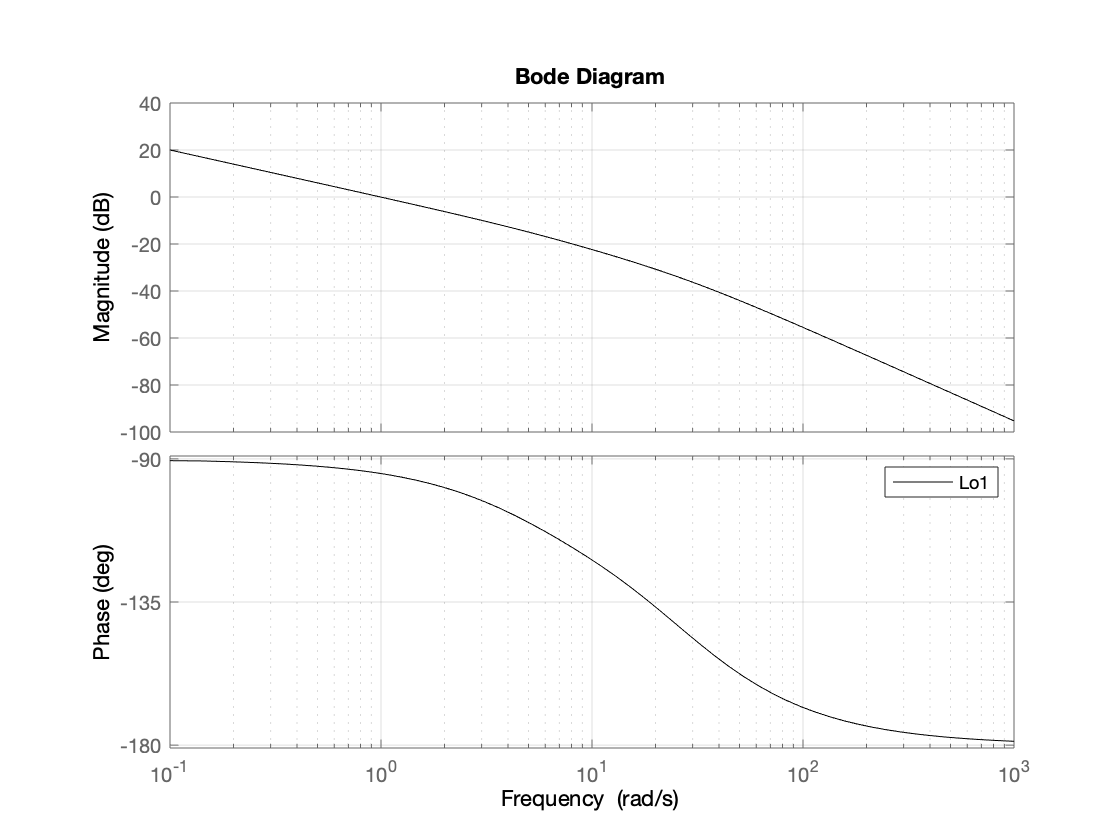

Lo1 = Rdo1*G2;
bode(Lo1, 'black'); grid on; legend ();

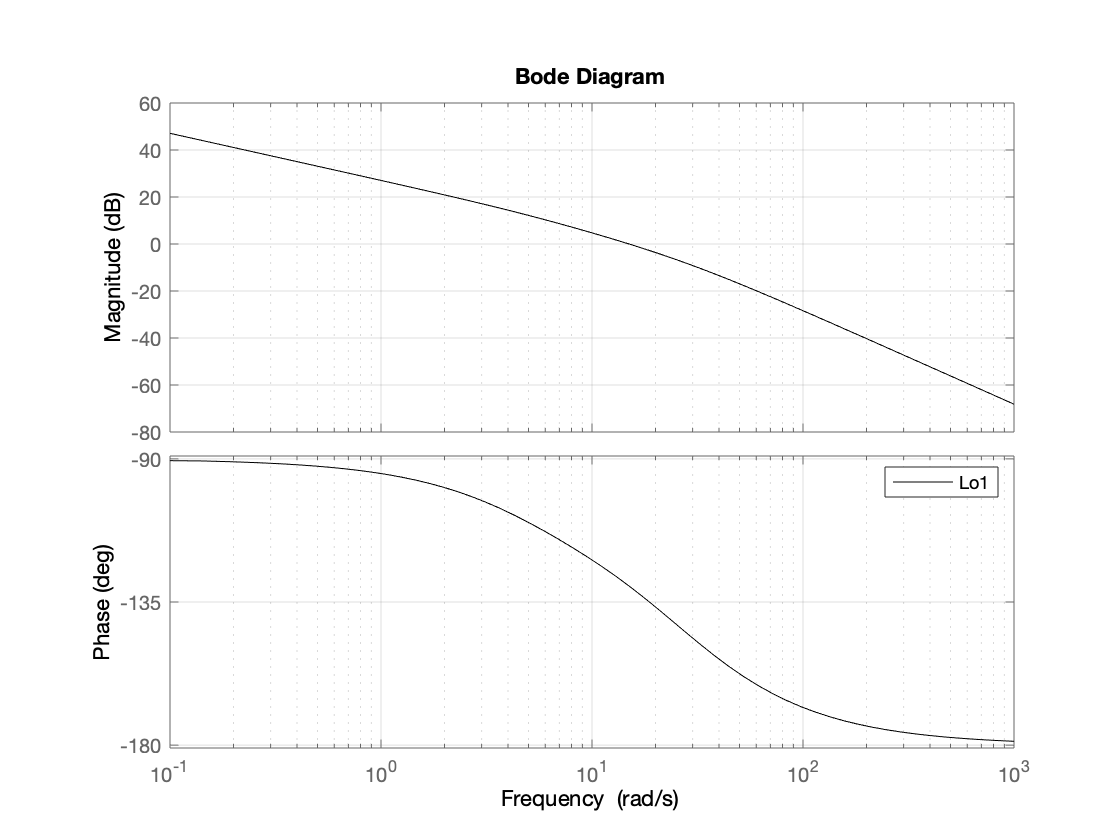

%utilizzo il guadagno statico libero per imporre l'attraversamento
mu3 = 22.64;

Lo1 = Rdo1*G2*mu3;
bode(Lo1, 'black'); grid on; legend ();
hold on;
hold off;

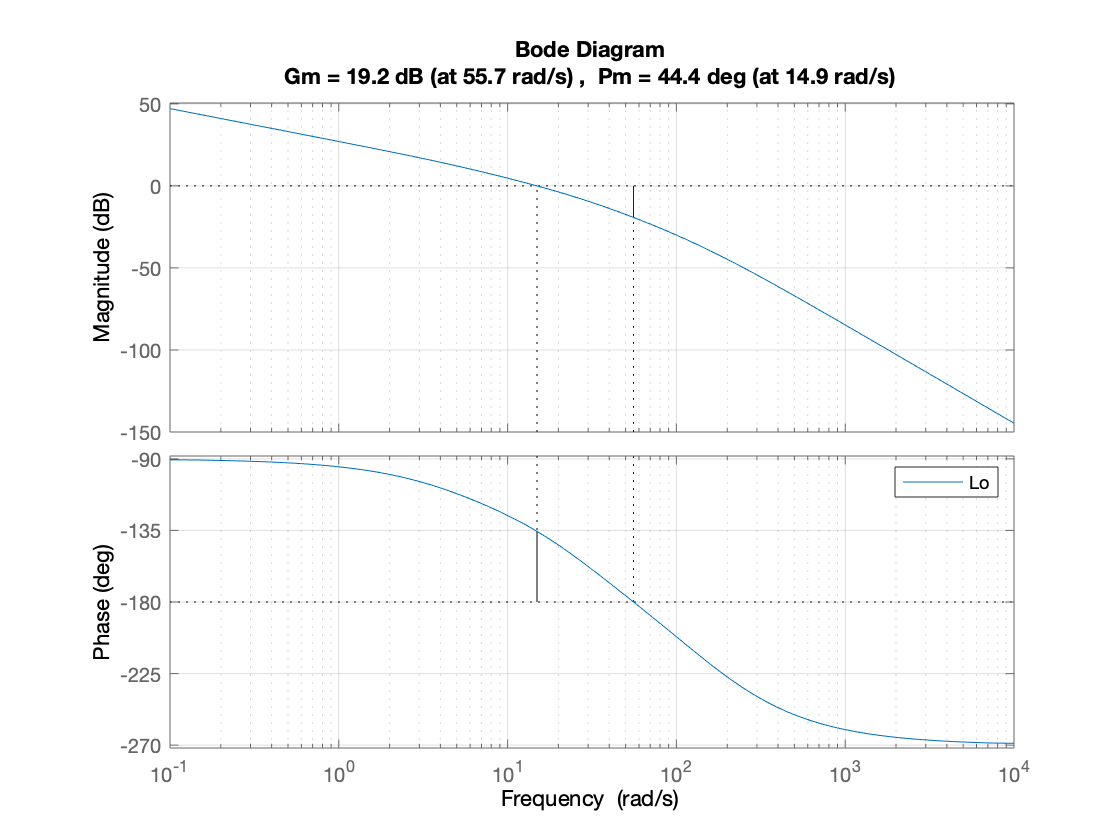

%Serve un polo di fiisca realizzabilità per moderare la Q ad elevate frequenze
Rdo2 = 1/((1/150)*s+1); %una decade dopo per non interferire a basse frequenze

Rdo = Rdo1*Rdo2*mu3; %regolatore dell'outer loop complessivo
[num_Rdo,den_Rdo] = tfdata(Rdo,'v');

Lo = Rdo*G2;
margin(Lo); grid on; legend ();

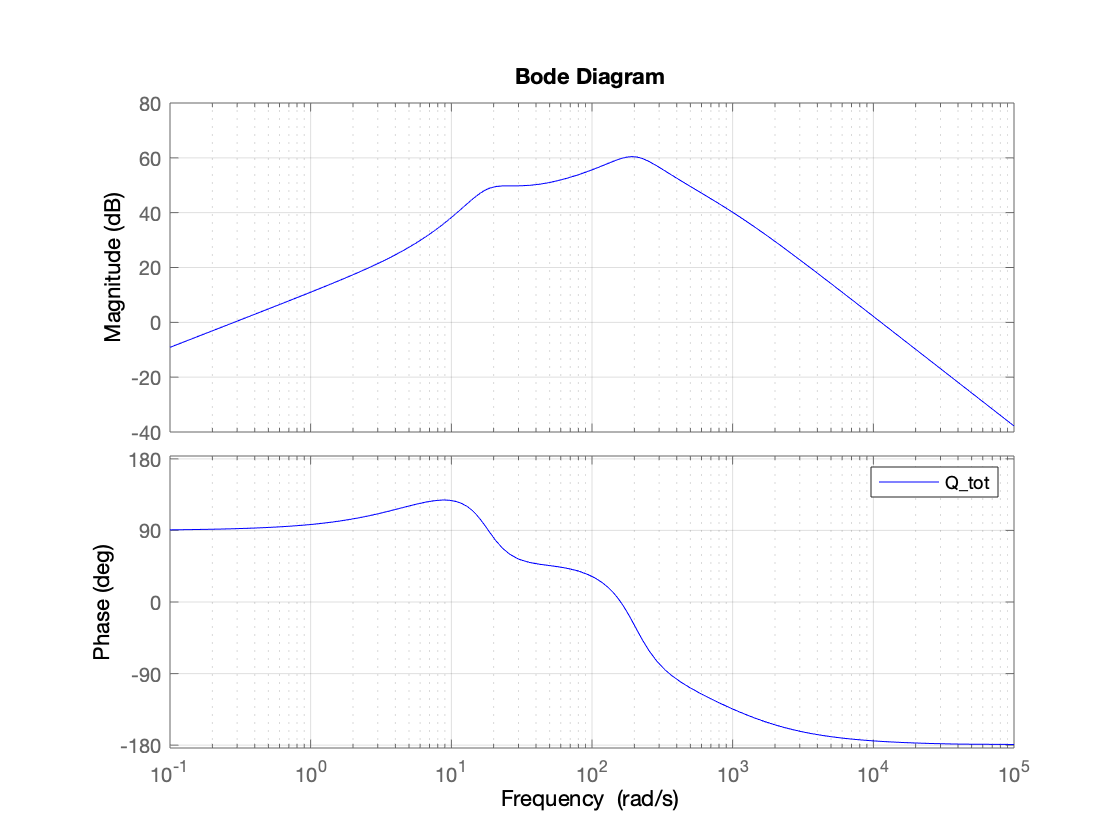

%valuto la Q del sistema complessivo 

Ro = Rdo; %Il regolatore dell'outer presenta solo la parte dinamica

R = Ro*Ri; %regolatore complessivo inner+outer
G = G1*G2; %sistema complessivo 
%Per trovare la Q_totale che tiene conto sia dell'inner che dell'outer, si
%deve trovare la f.d.t tra la U e la W
Q_tot = R/(1+G*R+G1*Ri);
bode (Q_tot, 'blue'); grid on; legend ();

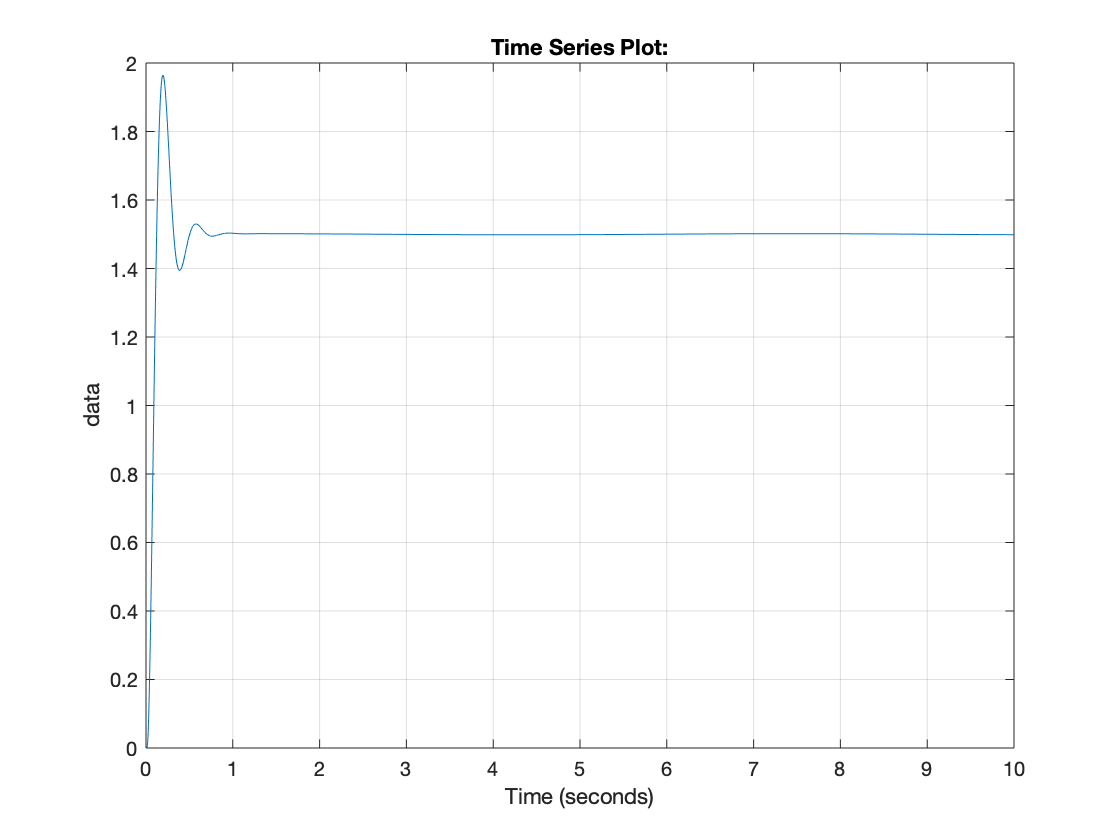

%pongo i filtri anti-aliasing e passa basso a 1 per evitare che alterino la 
%simulazione del sistema, dato il filtro anti-aliasing e passa basso vengono 
%introdotti più avanti
num_Raa_i = 1;
den_Raa_i = 1;
num_Raa_o = 1;
den_Raa_o = 1;
den_Rpf = 1;
num_Rpf = 1;

%pongo ad 1 anche i componenti discreti e i tempi di campionamento che per il 
% momento non ho definito e non mi interessano
NUMpf = 1;
DENpf = 1;
NUMdo = 1;
DENdo = 1;
NUMdi = 1;
DENdi = 1;
Ts_o = 1;
Ts_i = 1;

open sis_controllo_cascata;
sim('sis_controllo_cascata');
plot(out.y); grid on;

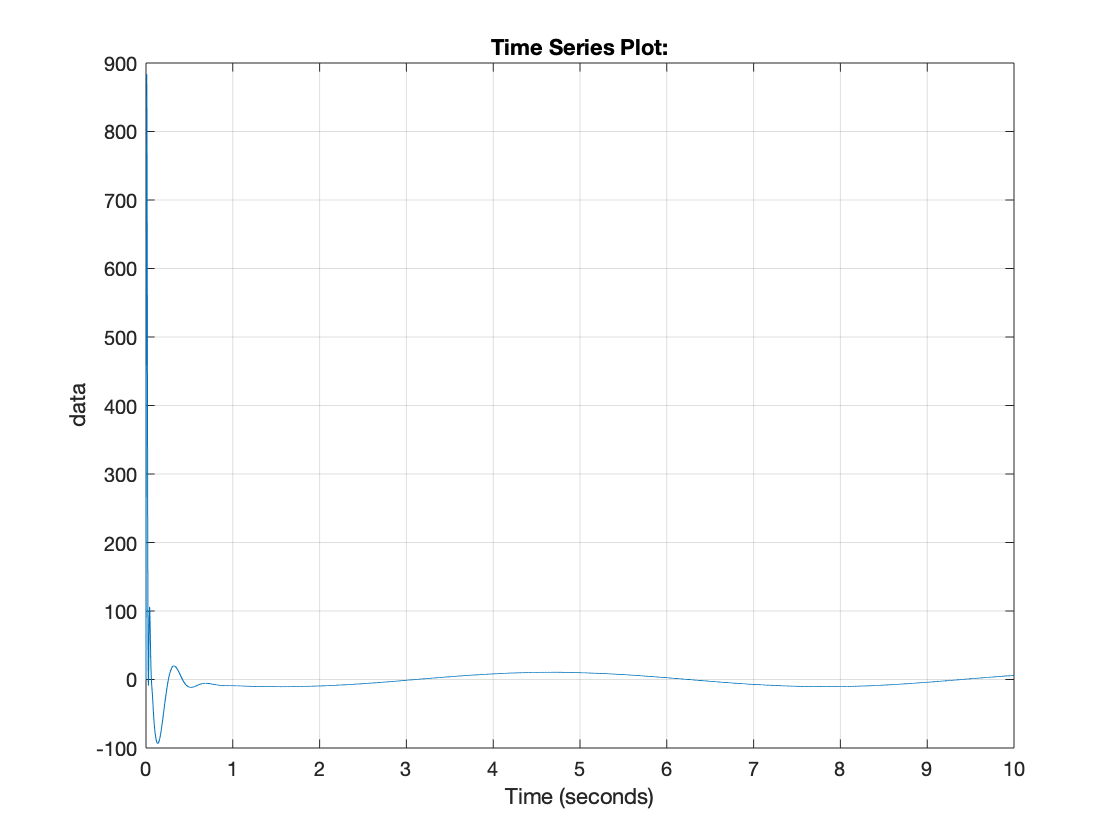

plot(out.u); grid on;

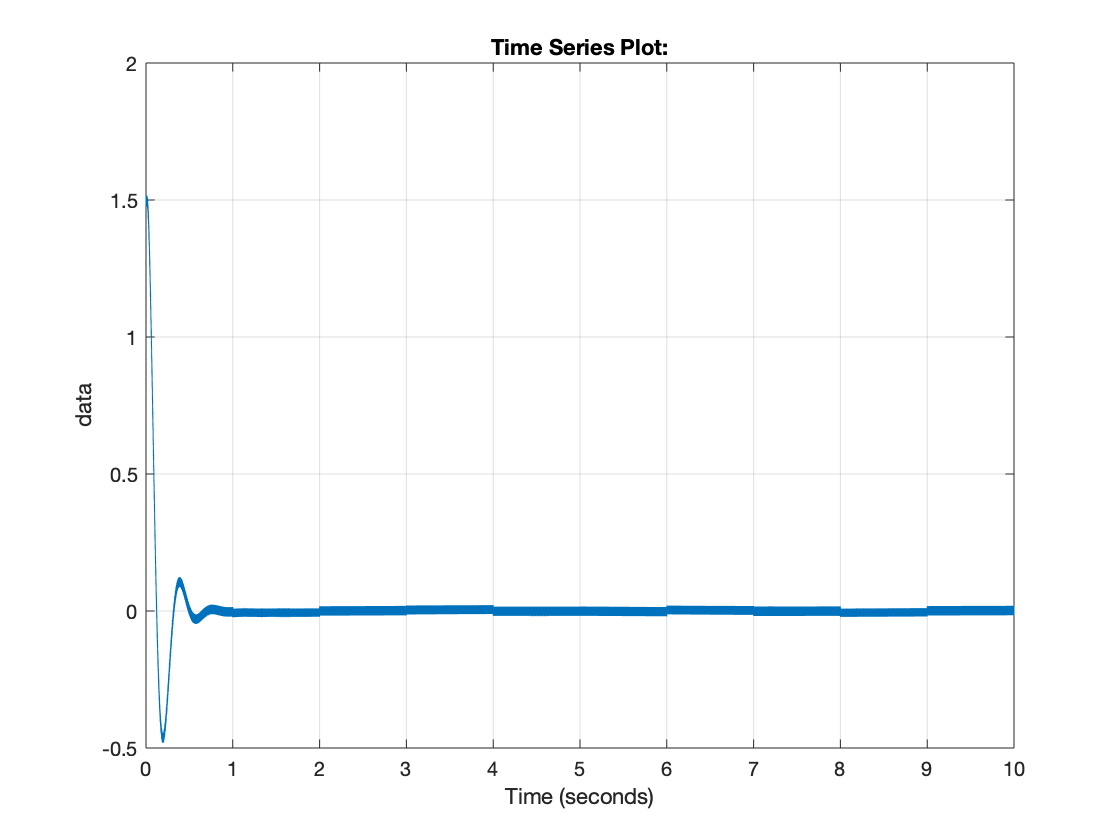

plot(out.e); grid on; 

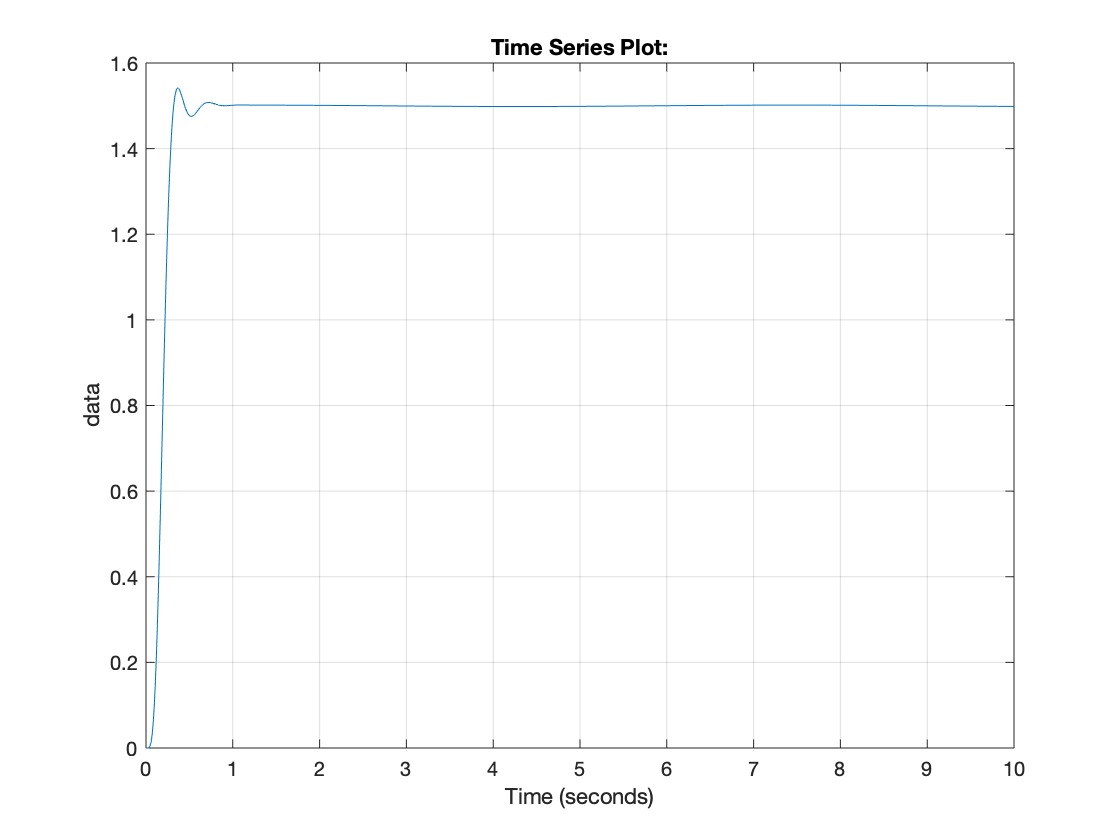

%Noto subito un forte picco di sovraelongazione che raggiunge una vetta di
%circa 1.95. Per risolvere questo problema  applico un preflitro del
%secondo ordine.
tauf = 0.65/9; %la pulsazione di taglio del prefiltro è 9r/s
Rpf= 1/(1+tauf*s)^2; 
[num_Rpf,den_Rpf] = tfdata(Rpf,'v');

%(eseguo lo schema simulink per aggiornare i dati del prefiltro)

%verifico i benifici del mio prefiltro
sim('sis_controllo_cascata');
plot(out.y); grid on;

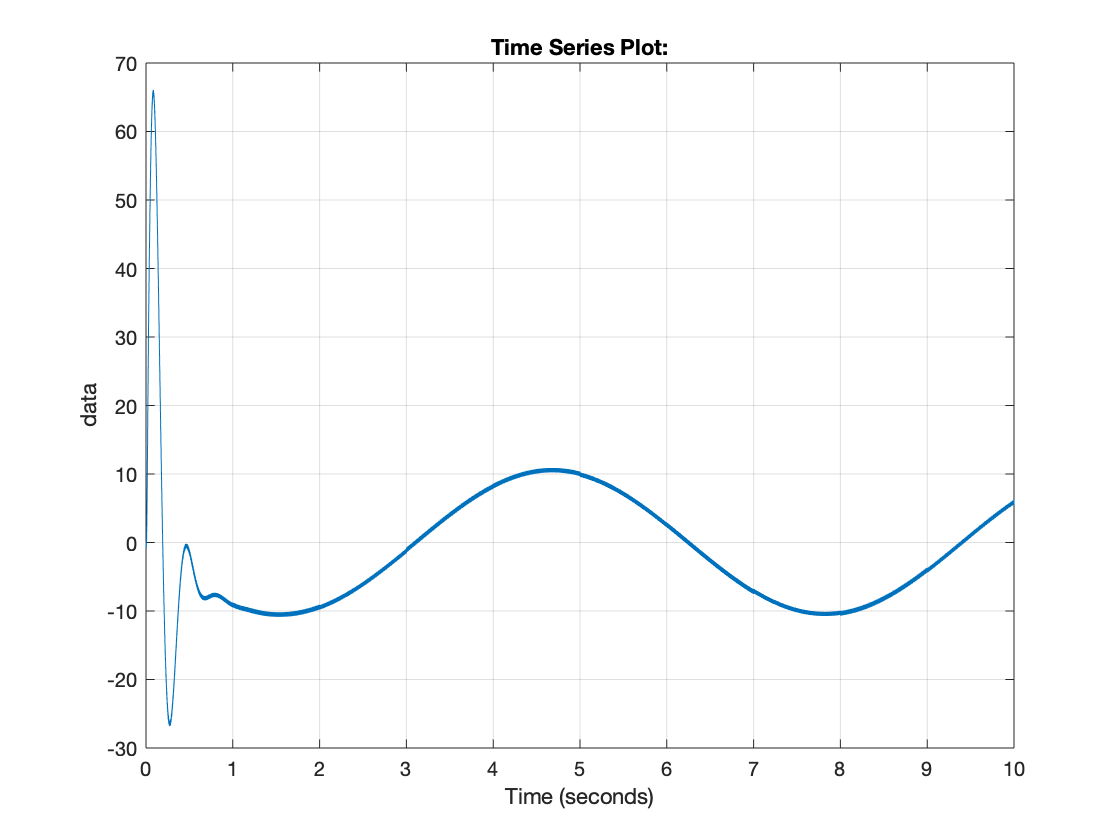

plot(out.u); grid on;

 **DISCRETIZZAZIONE DEL REGOLATORE INNER E OUTER**

Poiché il regolatore è stato progettato come tempo continuo è necessaria un'interfaccia D/A per la discretizzazione del regolatore. Per fare questo ho utilizzato il teorema di Shannon e la "regola pratica" ad esso associata, che mi hanno permesso di determinare un intervallo di valori validi per il tempo di campionamento, andando poi a scegliere quello più adeguato al mio progetto. L'alpha scelto per applicare la "regola pratica" è la media tra 5 e 10 (cioè 7.5).

Per evitare poi il fenomeno dell'aliasing ho introdotto un filtro anti-aliasing con:                                         omega_c < omega_aa < omega_s/2

INNER LOOP

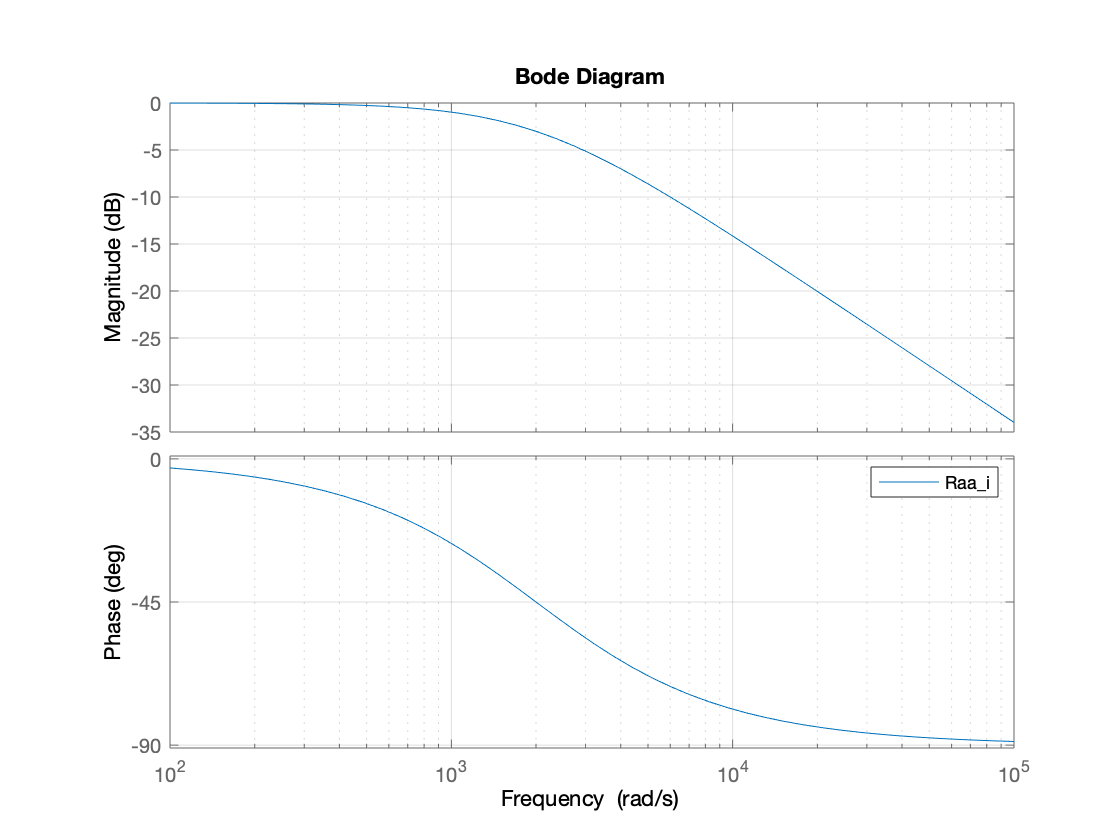


%La pulsazione di attraversamento dell'inner loop è omega_c = 156r/s dunque
%1170 < omega_s_i < 11700
omega_s_i = 10000; %mettendo il valore medio di omega_s_i, cioè 6435r/s,
%ottengo un tempo di campionamento probabilmente insufficiente dei
%problemi nella risposta una volta discretizzati i regolatori. Il principale 
%problema riscontrato è dovuto alla sovraelongazione, questo perché un 
%ricostruttore del primo ordine è assimilabile ad un puro ritardo pari a metà 
%del tempo di campionamento. Se il tempo di campionamento non è sufficientemente
%piccolo questo causa una perdita di fase sostanziosa e quindi un diminuire del
%margine di fase che causa la sovraelongazione indesiderata.
%Bisogna comunque ricordare però che un tempo di campionamento eccessivamente 
%ridotto porta a costi elevati di hardware.
Ts_i = 2*pi/omega_s_i; %tempo di campionamento dell'inner loop

%filtro anti-aliasing con 156 < w_aa_i < 5000
tau_aa_i = 1/2000;%Anche se il valore di mezzo di w_aa_i sarebbe 1686r/s, 
%si ottiene una miglior risposta con w_aa_i = 2000r/s;
Raa_i = 1/((s*tau_aa_i)+1);
bode (Raa_i); grid on; legend ();

[num_Raa_i,den_Raa_i] = tfdata(Raa_i,'v');

[num_Ri,den_Ri] = tfdata(Ri,'v');
%Discretizzazione del regolatore dell'inner loop
[NUMdi,DENdi] = c2dm (num_Ri,den_Ri,Ts_i,'tustin');

OUTER LOOP

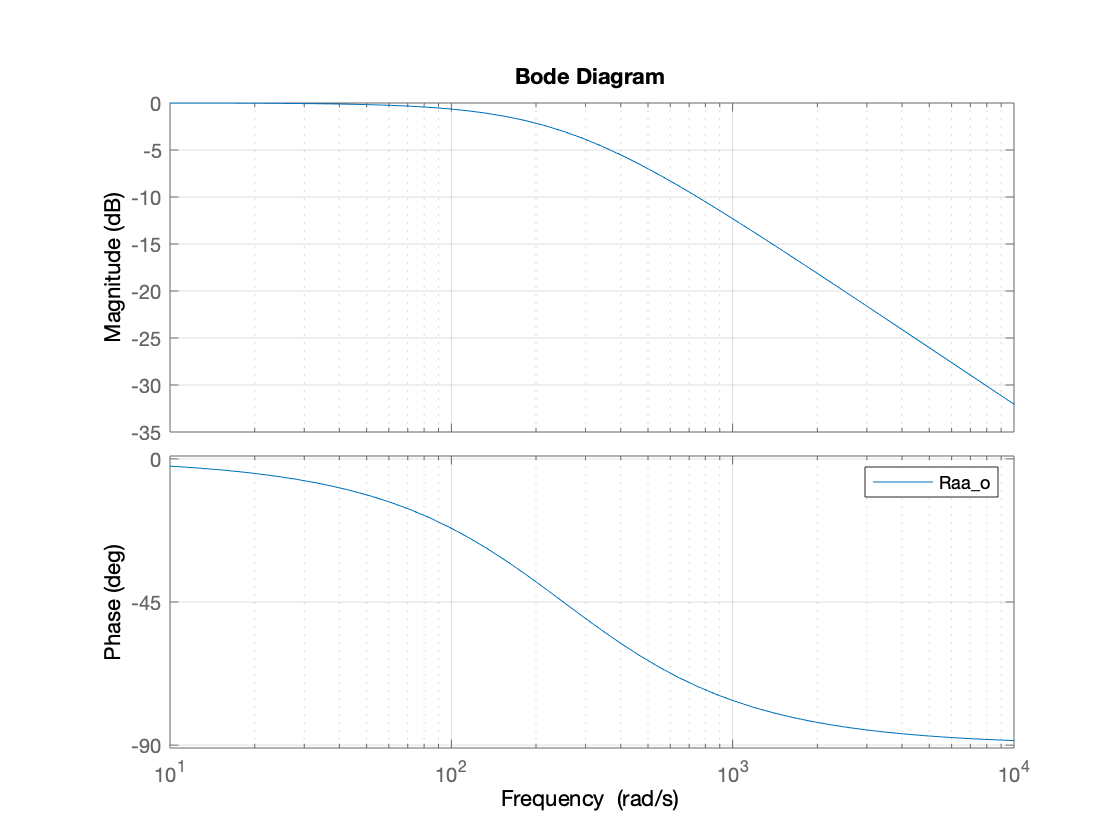

%La pulsazione di attraversamento dell'outer loop è omega_c = 15r/s dunque 
%112.5 < omega_s_o < 1125
omega_s_o = 1000;%%mettendo il valore medio di omega_s_o, cioè 618.75r/s,
%ottengo un tempo di campionamento probabilmente insufficiente dei
%problemi nella risposta una volta discretizzati i regolatori. Il principale 
%problema riscontrato è dovuto alla sovraelongazione, questo perché un 
%ricostruttore del primo ordine è assimilabile ad un puro ritardo pari a metà 
%del tempo di campionamento. Se il tempo di campionamento non è sufficientemente
%piccolo questo causa una perdita di fase sostanziosa e quindi un diminuire del
%margine di fase che causa la sovraelongazione indesiderata.
%Bisogna comunque ricordare però che un tempo di campionamento eccessivamente 
%ridotto porta a costi elevati di hardware.
Ts_o = 2*pi/omega_s_o; %tempo di campionamento dell'outer loop

%filtro anti-aliasing con 15 < w_aa_o < 500
tau_aa_o = 1/250;%Anche se il valore di mezzo di w_aa_i sarebbe 162r/s, 
%si ottiene una miglior risposta con w_aa_i = 250r/s;
Raa_o = 1/((s*tau_aa_o)+1);
bode (Raa_o); grid on; legend ();

[num_Raa_o,den_Raa_o] = tfdata(Raa_o,'v');

[num_Ro,den_Ro] = tfdata(Ro,'v');
%Discretizzazione del regolatore dell'outer loop
[NUMdo,DENdo] = c2dm (num_Ro,den_Ro,Ts_o,'tustin');
%Discretizzazione del pre-filtro
[NUMpf,DENpf] = c2dm (num_Rpf,den_Rpf,Ts_o,'tustin');

%(sostituire i componenti continui con quelli discreti)
sim('sis_controllo_cascata');
plot(out.y); grid on;

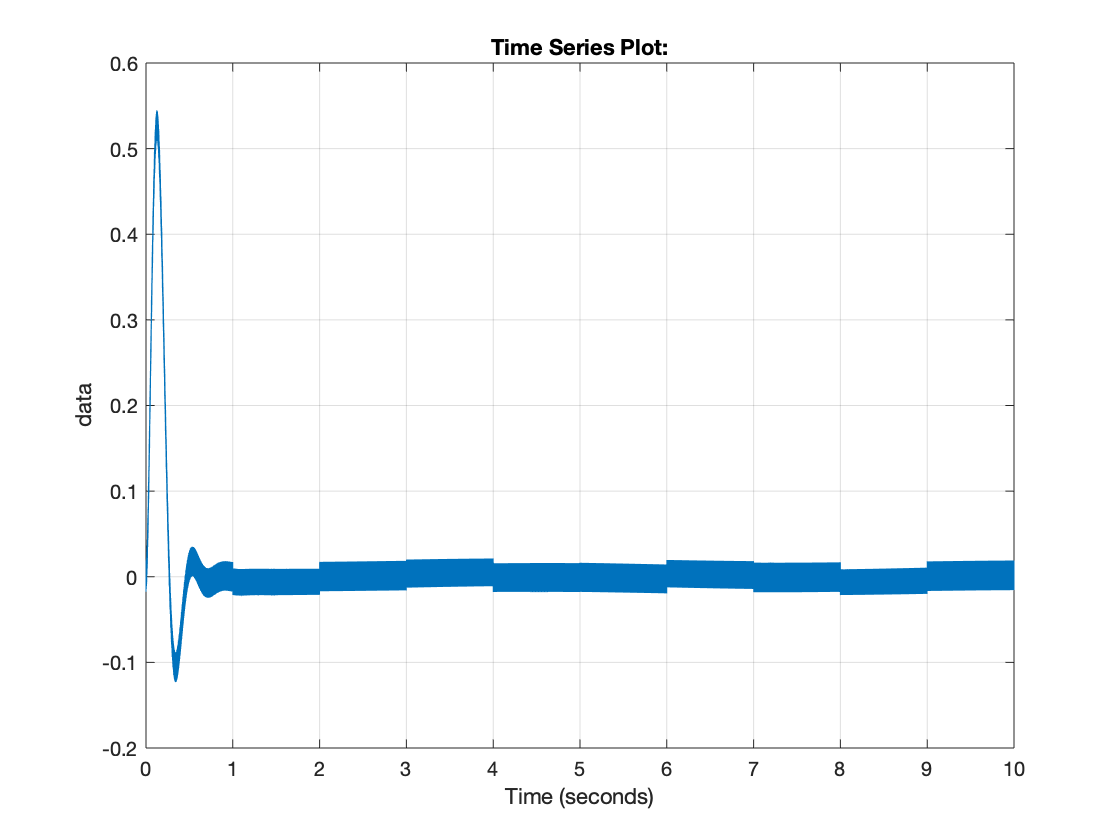

plot(out.u); grid on;